# Main code to run the sensitivity example

This is an example of a 2d mass translating on the space with unkonwn mass and unkown friction coefficient.

Firstly, we generate the required functions by running the code:

casadi_path = "..\..\..\casadi_matlab";
addpath(casadi_path)
generate_functions;

Building with 'MinGW64 Compiler (C)'.
MEX completed successfully.
Building with 'MinGW64 Compiler (C)'.
MEX completed successfully.
Building with 'MinGW64 Compiler (C)'.
MEX completed successfully.
Building with 'MinGW64 Compiler (C)'.
MEX completed successfully.
Building with 'MinGW64 Compiler (C)'.
MEX completed successfully.
Building with 'MinGW64 Compiler (C)'.
MEX completed successfully.
Building with 'MinGW64 Compiler (C)'.
MEX completed successfully.
Building with 'MinGW64 Compiler (C)'.
MEX completed successfully.
Building with 'MinGW64 Compiler (C)'.
MEX completed successfully.


This is my function that generate the model and compute the derivative wxploiting CASADI.

**Question 1**: Are we sure that everything is correct?

We can check it by making 4 simulations (2 for each parameter) and comparing the sensitivity computed through the function with the real one computed as$\frac{\Delta q}{\Delta p_i }$ with $\Delta p_i$ very small.

You can run it using the function:

validate_sensitivity

You see two figures (1 for each parameter) and 6 plots in each figure: the sensitivity of each q (position and velocity). You can see that the theoretical sensitivity and the computed one are the same.

## Optimization

We are now interested in computing the optimization.

I have made a very simple case with casadi in which you want to minimize $||\Pi \left(t_f \right)||$ generating a polynomial trajectory of order $8$ using a superquadric of order k=50. The constraints that you have are:


$$\begin{array}{l}
x_{\mathrm{des}} \left(t_0 \right)=x_0 \\
x_{\mathrm{des}} \left(t_f \right)=x_f \\
{\dot{x} }_{\mathrm{des}} \left(t_0 \right)=0\\
{\dot{x} }_{\mathrm{des}} \left(t_f \right)=0\\
{\ddot{x} }_{\mathrm{des}} \left(t_0 \right)=0\\
{\ddot{x} }_{\mathrm{des}} \left(t_f \right)=0
\end{array}$$


Run the code (be patient, it may take some minutes):

Creating Function
Starting Solver
This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:       81
Number of nonzeros in inequality constraint Jacobian.:    54018
Number of nonzeros in Lagrangian Hessian.............:      378

Total number of variables............................:       27
                     variables with only lower bounds:        0
                variables with lower and upper bounds:       27
                     variables with only upper bounds:        0
Total number of equality constraints.................:       18
Total number of inequality constraints...............:     6006
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:     6006
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  2.4366542e-04 2.75e+00 1.28e-05  -1.0

A =    -0.0001   -0.0005    0.0001
    0.0030    0.0092   -0.0030
   -0.0246   -0.0745    0.0246
    0.1050    0.3046   -0.1050
   -0.2447   -0.6737    0.2447
    0.2759    0.7347   -0.2759
         0         0         0
         0         0         0
         0         0         0


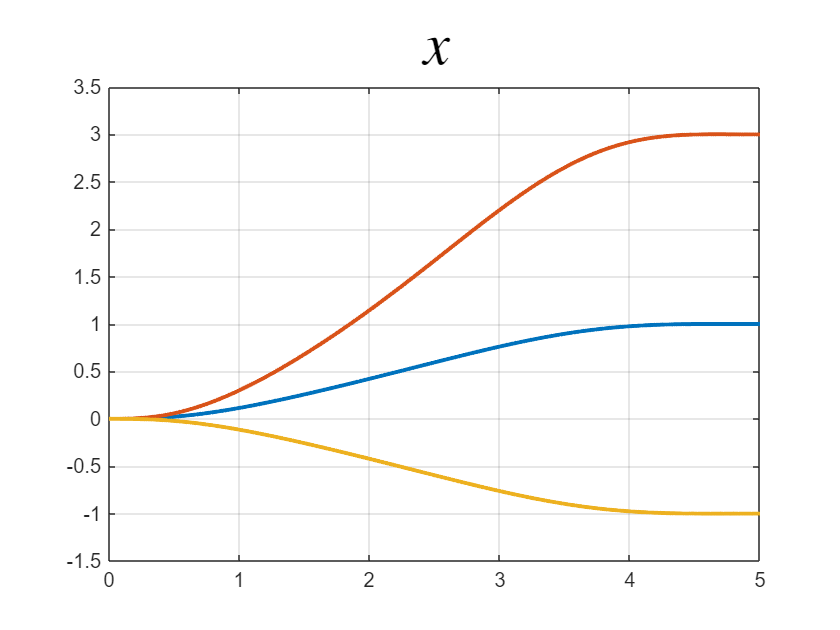

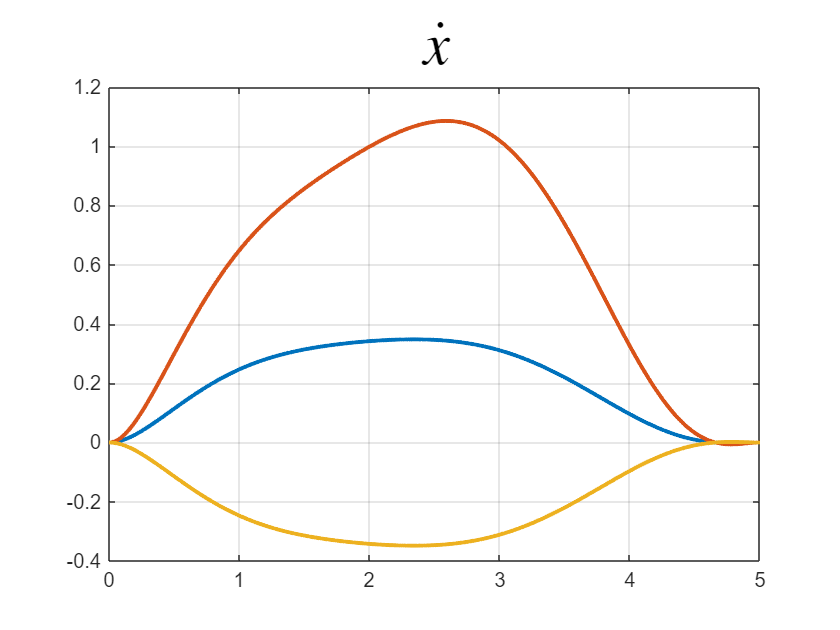

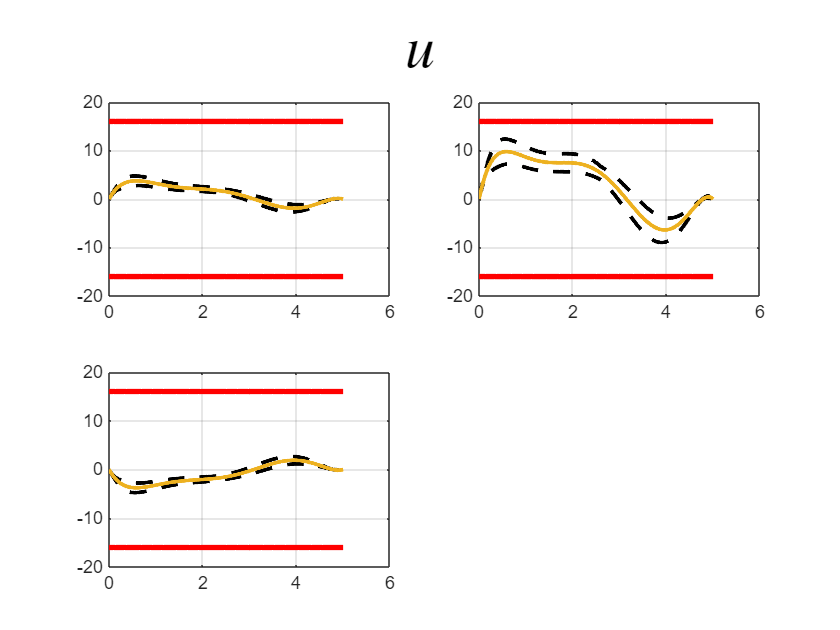

optimization

You see the plots showing the position and velocity of the system, and also the input with the tubes.